# EULER

clc


## Initial Conditions


y0 = 70.0;
vy0 = -15; % Va a la derecha
g = -9.81;

## Time and stepSize

tf = 10; % 'Cause its really fast
N = 1000; % 'Cause it's Euler hahahahah
h = tf / N*20;


## Vector Arrays


y = zeros(N,1); y(1) = y0; % Added the initial condition

vy = zeros(N,1); vy(1) = vy0; % Added the initial condition

t = zeros(N,1); t(1) = 0.0; % Simulation starts at 0 s

## Diff equations


dy =@ (t, vy) g*t + vy;
dvy =@ (t, vy) (g*t.^2)/2 + vy*t;

## **Menu**

    ymax=70;
    naco = input("1) Caso A \n 2) Caso B \n 3) Caso C \n [ENTER] para continuar \n");
    op=input("¿Que caso desea?");
    if op==1
        vy0=input("¿Con que velocidad sale el trampolin?");
        vy = zeros(N,1); vy(1) = vy0;
        td=((-vy0)/g);
        td = ceil(td);
        t(1)= 0;
        for n=1:td
            vy(n+1)=vy(n)+g*h; 
            y(n+1)=y(n)+vy(n)*h+0.5*t(n)*g;
            t(n+1)=t(n)+1;
            ymax = y(n);
        end
    
        td=ceil(td);
        tdn=((-vy0)/g)*2;
        tdn=ceil(tdn);
        for n=td:tdn
            vy(n+1)=vy(n)+g*h;
            y(n+1)=y(n)+vy(n)*h+0.5*t(n)*g;
            t(n+1)=t(n)+1;
        end      
    end
    
    if op==2
        vy0=input("Con que velocidad se lanza de clavado?");
        tdn=1;
        vy(1)=-vy0;
    end
    
    if op==3
        vy0=0;
        tdn=1;
        vy(1)=vy0;
    end


## Euler method

    for n=tdn:N-1
        if ((y(n) < 38))
            break;
        end
        t(n+1) = t(n)+h;
        %First step calculate the constants k's in positions
       
        k1=h*dy(t(n), vy(n));
        y(n+1)=y(n)+k1;
        
        
        % Calculate velocity k's 
        k1=h*dvy(t(n), vy(n));
        vy(n+1)=vy(n)+k1;
    end
    disp("Velocidad inicial")

Velocidad inicial


    disp(vy0)

    18



    disp("Tiempo en alcanzar la longitud natural de la cuerda: ")

Tiempo en alcanzar la longitud natural de la cuerda: 


    disp(t(n))

    1.4000



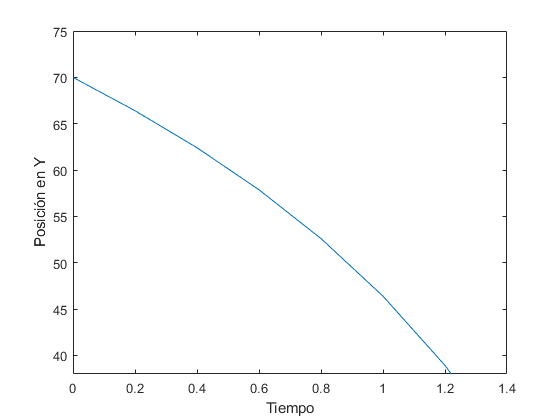

    
    
    z = 38;
    yplot=y;
    yplot(yplot==0)=nan;
    tplot=t;
    tplot(yplot==0)=nan;
    plot(tplot,yplot); 
    xlabel('Tiempo') 
    ylabel('Posición en Y') 
    tmax=t(n);
    ymax=ceil(ymax + 5);
    ylim([z ymax]);
    xlim([0 tmax]);

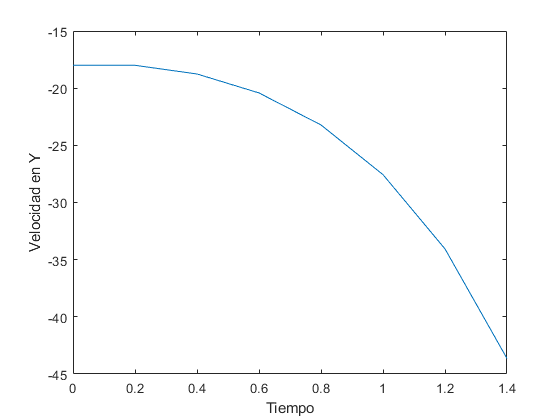

    
    vyplot=vy;
    vyplot(vyplot==0)=nan;
    plot(tplot,vyplot); 
    xlabel('Tiempo') 
    ylabel('Velocidad en Y') 